%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                                         %
%                   PHASE-AWARE AUDIO INPAINTING (PHAIN)                  %
%                                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all
clear
clc
    
rng(0)

## paths

addpath(genpath('dataset'))
addpath('utils')
addpath(genpath('phase_correction'));
addpath('PHAIN');

## loading

soundDir = "dataset/sine_wave";
ext = ".wav";
Sounds = dir(soundDir + "*" + ext);
NN = length(Sounds);
data = cell(NN,1);
info = audioinfo(Sounds(1).name);
fs = info.SampleRate;
for nn = 1:NN
    data{nn} = audioread(Sounds(nn).name);
end
clear audio info

## settings

%gaps = 5:5:50 % [ms]
gaps = 1:2; % [1 2 3 4 5] 
M = length(gaps);

N = 2; % # of gaps

methodLabels = {'U_PHAIN'};

for i = 1:length(methodLabels)
    solution.(methodLabels{i}) = cell(NN);  % initialization of restored results
end
SNR  = NaN(NN, M, N, length(methodLabels));  % SNR per gap
TIME = NaN(NN, M, N, length(methodLabels));  % execution time per gap
SNR_procedure = cell(NN, M, N, length(methodLabels));  % iterative behavior

## parameters

winLen = 2800;
shiftLen = winLen/4;
FFTnum = winLen;

% parameter setting for PHAINs
param.a = shiftLen;
param.M = FFTnum;
param.w = winLen;

paramsolver.epsilon = 0.01;  % for stopping criterion

paramsolver.tau = 0.25;  % step size
paramsolver.sigma = 1;  % step size
paramsolver.alpha = 1;  % relaxation parameter

paramsolver.lambda = 1;  % threshold (regularization parameter)

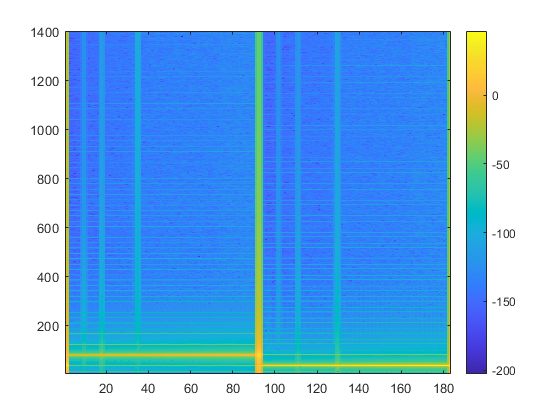

%%%%%% fast DGT %%%%%%%%
[win, ~] = generalizedCosWin(winLen, 'hanning');
tight_win = calcCanonicalTightWindow(win, shiftLen);
tight_win = tight_win/norm(tight_win)*sqrt(shiftLen/winLen);

zeroPhaseFlag = true;
[sigIdx, sumIdx, sumArray, ifftArray, rotIdx] = precomputationForFDGT(length(data{1}), winLen, shiftLen, FFTnum);

signal_x = data{1};
spectrogram_x= FDGT(signal_x, tight_win, sigIdx, FFTnum, rotIdx, zeroPhaseFlag);
%signal_after = invFDGT(spectrogram_x, tight_win, sumIdx, sumArray, ifftArray, rotIdx, zeroPhaseFlag)*winLen
%spectrogram_x2= FDGT(signal_after, tight_win, sigIdx, FFTnum, rotIdx, zeroPhaseFlag);
figure, imagesc(20*log10(abs(spectrogram_x))), colorbar, axis xy

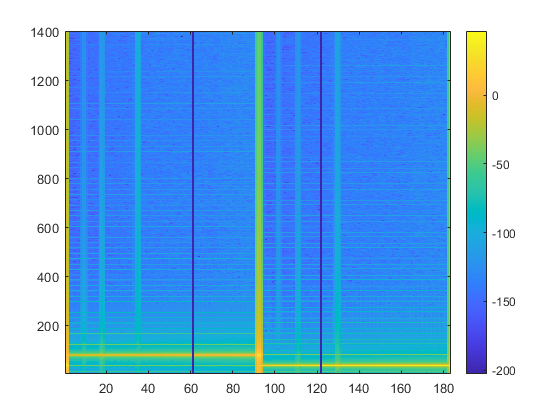


% create a mask with the size of dgt coef
num_of_coef = size(real(spectrogram_x(1,:)));
spec_size = size(real(spectrogram_x));
my_mask = ones(spec_size);

% create a hole in mask
index = num_of_coef(2)-round(num_of_coef(2)/3);
index2 = num_of_coef(2)-round(2*num_of_coef(2)/3);
my_mask(:,index:index) = 0;
my_mask(:,index2:index2) = 0;

%inpainted signal
gapped_spectrogram = spectrogram_x.*my_mask;
figure, imagesc(20*log10(abs(gapped_spectrogram))), colorbar, axis xy

## inpainting



indeces = [index,index2];
full.length =  length(spectrogram_x(1,:));
segment.length = 8;
for i = 1:length(methodLabels)
    solution.(methodLabels{i}){1} = gapped_spectrogram;
end
for n = 1:N
    indxs_gap = [indeces(n):indeces(n)];
    if length(indxs_gap) ~= segment.length
        to_pad = segment.length - length(indxs_gap);
        to_pad_each = 2;
        indxs_gap = [(indeces(n)-to_pad_each):(indeces(n)+to_pad_each)];
    end
    disp(indxs_gap)
    fprintf('\nGap Number: %d / %d\n', n, N)
    % making a gap
    segment.mask = my_mask(:,indxs_gap);
    segment.data = spectrogram_x(:,indxs_gap);
    segment.gapped = segment.data.*segment.mask;
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%% U-PHAIN %%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    fprintf('U-PHAIN...\n')
    tic
    param.type = 'U';
    paramsolver.I = 100;
    paramsolver.J = 10;
    
    [segment.solution] = PHAINmain_TF(segment.gapped, segment.mask, param, paramsolver, segment.data);
    
    solution.U_PHAIN{1}(:,indxs_gap) = segment.solution;
    %TIME(nn, m, n, 6) = toc;

end

   120   121   122   123   124




Gap Number: 1 / 2


U-PHAIN...


    59    60    61    62    63




Gap Number: 2 / 2


U-PHAIN...


%first = invFDGT(segment.gapped, tight_win, sumIdx, sumArray, ifftArray, rotIdx, zeroPhaseFlag)*winLen;
%segment.solution = FDGT(first, tight_win, sigIdx, FFTnum, rotIdx, zeroPhaseFlag);
%figure, imagesc(20*log10(abs(segment.solution))), colorbar, axis xy

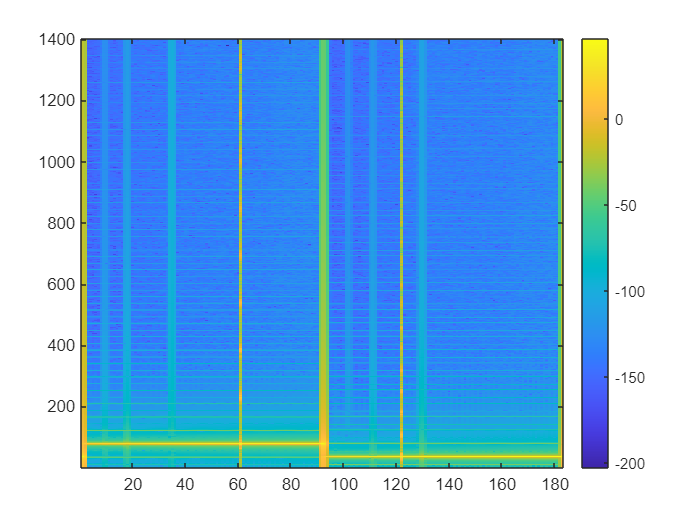

figure, imagesc(20*log10(abs(solution.U_PHAIN{1}))), colorbar, axis xy

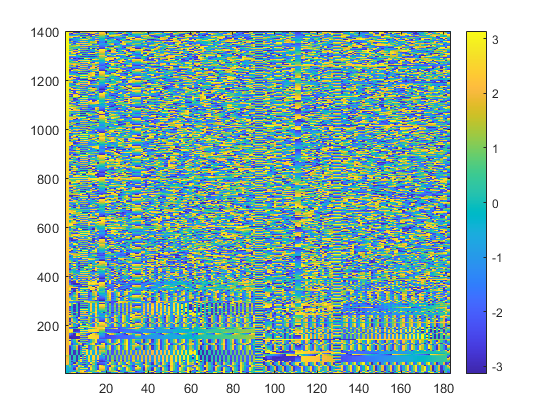

figure, imagesc(angle(solution.U_PHAIN{1})), colorbar, axis xy

ending = invFDGT(solution.U_PHAIN{1}, tight_win, sumIdx, sumArray, ifftArray, rotIdx, zeroPhaseFlag)*winLen;
snr(abs(signal_x(98000:99000)), abs(signal_x(98000:99000)-ending(98000:99000)))

ans = 310.7883

calcSNR(signal_x(98000:101000), ending(98000:101000))

ans = 311.0785

## plot

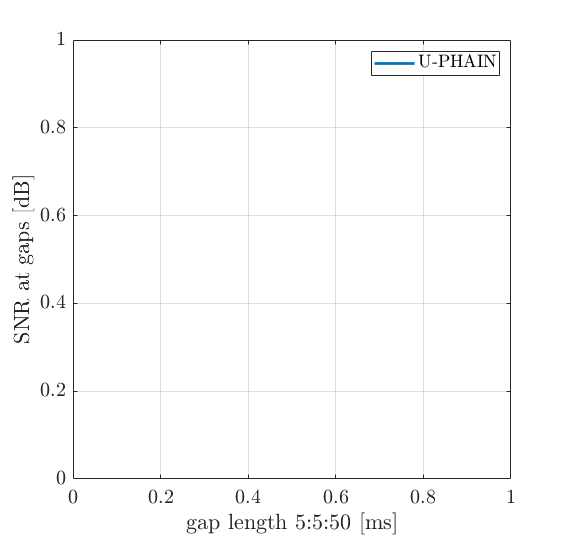

snr_vec = squeeze(median(SNR, [1,3]));
figure(Position = [614 157 873 830])
p = plot(snr_vec, LineWidth = 2);
grid on
legend(["U-PHAIN"], Interpreter = 'latex')
xlabel('gap length 5:5:50 [ms]', Interpreter = 'latex')
xticks = 1:10;
xticklabels = ["5", "10", "15", "20", "25", "30", "35", "40", "45", "50"];
ylabel('SNR at gaps [dB]', Interpreter = 'latex')
ax = gca;
ax.FontSize = 15;
ax.TickLabelInterpreter = 'latex';